## **Covid Detection Transfer Learning (densenet201)**

## Load Data 

% Data splits provided by the UCSD data github.
imdsTest = imageDatastore(fullfile('COVID19_CT_seg_20cases', 'test'),'IncludeSubfolders',true,'LabelSource','foldernames');
imdsTrain = imageDatastore(fullfile('../ucsd_dataset'),'IncludeSubfolders',true,'LabelSource','foldernames');

## Load Pretrained Network

net = resnet18;

Use `analyzeNetwork` to display an interactive visualization of the network architecture and detailed information about the network layers.

% analyzeNetwork(net);

net.Layers(1);
inputSize = net.Layers(1).InputSize;

## Replace Final Layers

Extract the layer graph from the trained network. If the network is a `SeriesNetwork` object, such as AlexNet, VGG-16, or VGG-19, then convert the list of layers in `net.Layers` to a layer graph.

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

Find the names of the two layers to replace. You can do this manually or you can use the supporting function [findLayersToReplace](matlab:edit(fullfile(matlabroot,'examples','nnet','main','findLayersToReplace.m'))) to find these layers automatically. 

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer];

In most networks, the last layer with learnable weights is a fully connected layer. Replace this fully connected layer with a new fully connected layer with the number of outputs equal to the number of classes in the new data set (5, in this example). In some networks, such as SqueezeNet, the last learnable layer is a 1-by-1 convolutional layer instead. In this case, replace the convolutional layer with a new convolutional layer with the number of filters equal to the number of classes. To learn faster in the new layer than in the transferred layers, increase the learning rate factors of the layer.

numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

The classification layer specifies the output classes of the network. Replace the classification layer with a new one without class labels. `trainNetwork` automatically sets the output classes of the layer at training time. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

## Freeze Initial Layers

layers = lgraph.Layers;
connections = lgraph.Connections;

frozen = 1;
layers(1:frozen) = freezeWeights(layers(1:frozen));
lgraph = createLgraphUsingConnections(layers,connections);

## Train Network


 %***Image augmentation with variability***%
    % Use an augmented image datastore to automatically resize the training images. 
    % Specify additional augmentation operations to perform on the training images: 
    % randomly flip the training images along the vertical axis and randomly translate them 
    % up to 30 pixels and scale them up to 10% horizontally and vertically. 
    % Data augmentation helps prevent the network from overfitting and memorizing 
    % the exact details of the training images.  
    
    %{
    pixelRange = [-30 30];
    scaleRange = [0.9 1.1];
    rotRange = [-90 90];
    imageAugmenter = imageDataAugmenter( ...
        'RandXReflection',true, ...
        'RandXTranslation',pixelRange, ...
        'RandYTranslation',pixelRange, ...
        'RandXScale',scaleRange, ...
        'RandYScale',scaleRange, ...
        'RandRotation', rotRange);
    
    augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
        'DataAugmentation',imageAugmenter, 'ColorPreprocessing','gray2rgb');
    %}
    
% Augment data to fit new network
augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain,"ColorPreprocessing","gray2rgb");
augimdsTest = augmentedImageDatastore(inputSize,imdsTest,"ColorPreprocessing","gray2rgb");


Specify the training options.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'Verbose',false);

## Train the network using the training data.

net = trainNetwork(augimdsTrain,lgraph,options);

## Classify Test Images

Classify the test images using the fine-tuned network, and calculate the test accuracy.

[YPred,probs] = classify(net,augimdsTest);

% Get number of images.
numImages = size(YPred,1);
avg_accs = zeros([0,2]);
% Index tracker.
total_idx = 1;
for i = 1:numImages/3
    % Reset sums.
    covidSum = 0;
    noncovidSum = 0;
    % Get the sum of the patient's probability of covid and noncovid
    for j = 1:3
        covidSum = covidSum + probs(total_idx,1);
        noncovidSum = noncovidSum + probs(total_idx,2);
        total_idx = total_idx + 1;
    end
    avg_accs(i,1) = round(covidSum/3,4);
    avg_accs(i,2) = round(noncovidSum/3,4);
end

for i = 1:numImages/3
    % Print patient info and results
    if(i < 10)
        fprintf('Patient %d >> Avg COVID Probability = %.4f\n',i,avg_accs(i,1));
        fprintf('\t\t\t Avg nonCOVID Probability = %.4f\n',avg_accs(i,2));
    else
                fprintf('Patient %d >> Avg COVID Probability = %.4f\n',i,avg_accs(i,1));
        fprintf('\t\t\t  Avg nonCOVID Probability = %.4f\n',avg_accs(i,2));
    end
end

Patient 1 >> Avg COVID Probability = 0.9537


			 Avg nonCOVID Probability = 0.0463


Patient 2 >> Avg COVID Probability = 0.9506


			 Avg nonCOVID Probability = 0.0494


Patient 3 >> Avg COVID Probability = 0.9846


			 Avg nonCOVID Probability = 0.0154


Patient 4 >> Avg COVID Probability = 0.4223


			 Avg nonCOVID Probability = 0.5777


Patient 5 >> Avg COVID Probability = 0.6736


			 Avg nonCOVID Probability = 0.3264


Patient 6 >> Avg COVID Probability = 0.7593


			 Avg nonCOVID Probability = 0.2407


Patient 7 >> Avg COVID Probability = 0.9546


			 Avg nonCOVID Probability = 0.0454


Patient 8 >> Avg COVID Probability = 0.3550


			 Avg nonCOVID Probability = 0.6450


Patient 9 >> Avg COVID Probability = 0.3354


			 Avg nonCOVID Probability = 0.6646


Patient 10 >> Avg COVID Probability = 0.9046


			  Avg nonCOVID Probability = 0.0954


Patient 11 >> Avg COVID Probability = 0.9019


			  Avg nonCOVID Probability = 0.0981


Patient 12 >> Avg COVID Probability = 0.9813


			  Avg nonCOVID Probability = 0.0187


Patient 13 >> Avg COVID Probability = 0.8455


			  Avg nonCOVID Probability = 0.1545


Patient 14 >> Avg COVID Probability = 0.8086


			  Avg nonCOVID Probability = 0.1914


Patient 15 >> Avg COVID Probability = 0.8418


			  Avg nonCOVID Probability = 0.1582


Patient 16 >> Avg COVID Probability = 0.8543


			  Avg nonCOVID Probability = 0.1457


Patient 17 >> Avg COVID Probability = 0.9803


			  Avg nonCOVID Probability = 0.0197


Patient 18 >> Avg COVID Probability = 0.9625


			  Avg nonCOVID Probability = 0.0375


Patient 19 >> Avg COVID Probability = 0.4616


			  Avg nonCOVID Probability = 0.5384


Patient 20 >> Avg COVID Probability = 0.5668


			  Avg nonCOVID Probability = 0.4332


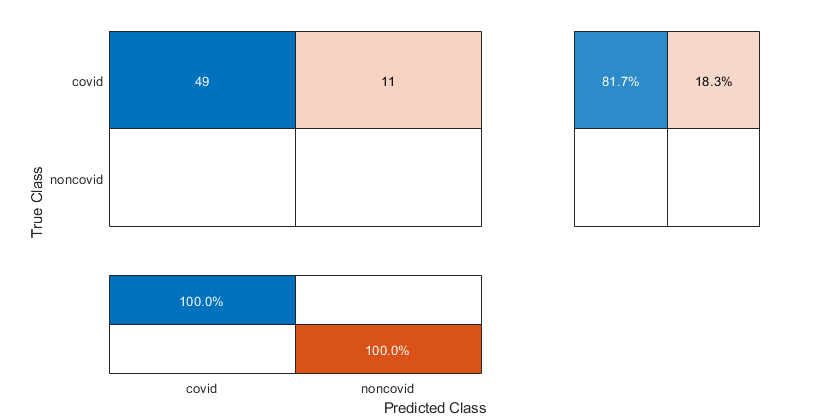


% Extract the class labels from the test data.
YTest = imdsTest.Labels;

accuracy = mean(YPred == YTest);

% Calculate Average F-score.
s = max(size(unique(YTest)));
conf_values = confusionmat(YTest, YPred);
tp_m = diag(conf_values); 
for i = 1:s
   % Get true positive, false negative, false positive
    TP = conf_values(1,1);
    FN = conf_values(1,2);
    FP = conf_values(2,1);
    TN = conf_values(2,2);
    
    % Calculate Recall, precision, fscore
    Recall = TP /(TP + FN);
    if isnan(Recall)
        Recall = 0;
    end
    % Calculate Precision
    Precision = TP / (TP + FP);
    if isnan(Precision)
        Precision = 0;
    end
    % Calculate FScore
    FScore = (2*(Precision * Recall)) / (Precision+Recall);
    if isnan(FScore)
        FScore = 0;
    end
end

% Display confusion chart.
fig = figure;
conf = confusionchart(YTest, YPred,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;

accuracy

accuracy = 0.8167

FScore

FScore = 0.8991

Display four sample validation images with predicted labels and the predicted probabilities of the images having those labels. With Actiavation Heatmaps

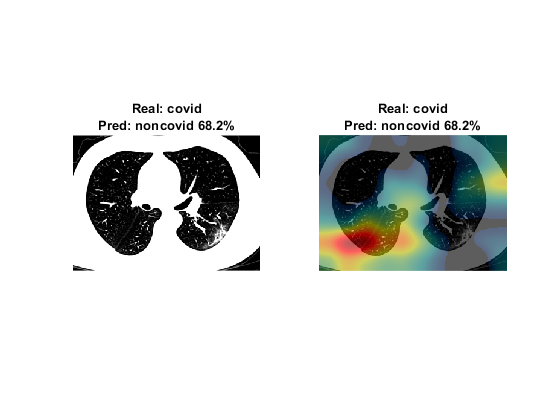

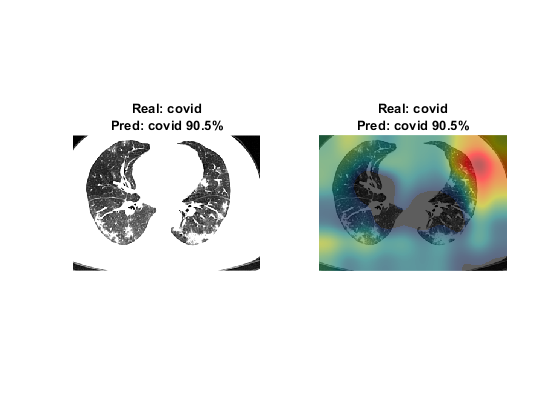

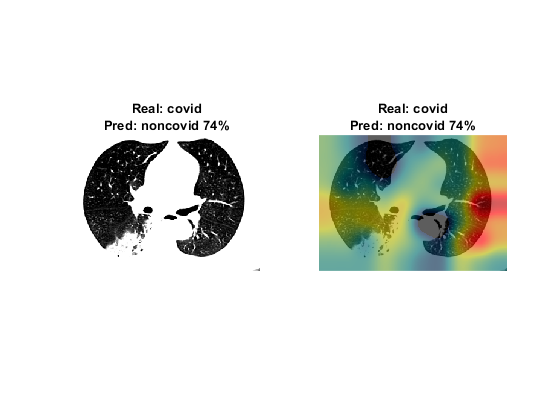

idx = randperm(numel(imdsTest.Files),3);
figure
for i = 1:3 
    I = readimage(imdsTest,idx(i));
    actlabel = YTest(idx(i));
    predlabel = YPred(idx(i));
    
    layerName = 'res5b_relu';
    
    %Compute the activations of the resized image
    % in the ReLU layer that follows the last convolutional layer of the network
    imResized = imresize(I,[inputSize(1), NaN]);
    imageActivations = activations(net,imResized,layerName);
    
    %global average pooling (get average of activations)
    scores = squeeze(mean(imageActivations,[1 2]));
    fcWeights = net.Layers(end-2).Weights;
    fcBias = net.Layers(end-2).Bias;
    
    %get predicted class/classes with highes scores for CAM
    scores =  fcWeights*scores + fcBias;
    [~,classIds] = maxk(scores,2);
    weightVector = shiftdim(fcWeights(classIds(1),:),-1);
    classActivationMap = sum(imageActivations.*weightVector,3);
    
    %get the top class labels and the final normalized class scores
    scores = exp(scores)/sum(exp(scores));     
    maxScores = scores(classIds);
    labels = class(classIds);
    
    %Plot the class activation map
    figure;
    subplot(1,2,1)
    imshow(imResized)
    title({"Real: " + string(actlabel), "Pred: " + string(predlabel) + " " + ...
    num2str(100*max(probs(idx(i),:)),3) + "%"});
    
    subplot(1,2,2)
    CAMshow(imResized,classActivationMap)
    title({"Real: " + string(actlabel), "Pred: " + string(predlabel) + " " + ...
    num2str(100*max(probs(idx(i),:)),3) + "%"});

end


drawnow




HELPER FUNCTIONS FOR CAM

function CAMshow(im,CAM)
    imSize = size(im);
    CAM = imresize(CAM,imSize(1:2));
    CAM = normalizeImage(CAM);
    CAM(CAM<0.2) = 0;
    cmap = jet(255).*linspace(0,1,255)';
    CAM = ind2rgb(uint8(CAM*255),cmap)*255;
    
    combinedImage = double(rgb2gray(im))/2 + CAM;
    combinedImage = normalizeImage(combinedImage)*255;
    imshow(uint8(combinedImage));
end


function N = normalizeImage(I)
    minimum = min(I(:));
    maximum = max(I(:));
    N = (I-minimum)/(maximum-minimum);
end